# Midterm November 16, 2018

## Exercise 1

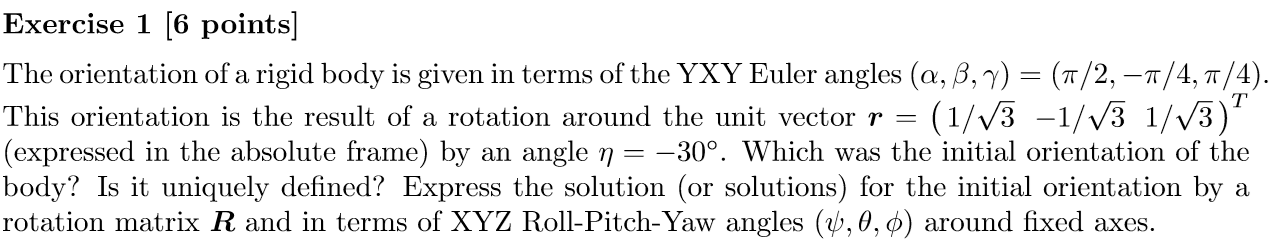

syms alpha beta gamma
[Rx Ry Rz] = getEulerRotationMatrices()

$$a = \left(\begin{array}{ccc} a_{1} & a_{2} & a_{3} \end{array}\right)$$

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(a_{1}\right) & -\sin\left(a_{1}\right)\\ 0 & \sin\left(a_{1}\right) & \cos\left(a_{1}\right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} \cos\left(a_{2}\right) & 0 & \sin\left(a_{2}\right)\\ 0 & 1 & 0\\ -\sin\left(a_{2}\right) & 0 & \cos\left(a_{2}\right) \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} \cos\left(a_{3}\right) & -\sin\left(a_{3}\right) & 0\\ \sin\left(a_{3}\right) & \cos\left(a_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% Eugler angle matrices are multipled in forward order. 
% Not reversed, like roll-pitch-yaw angles
RYXY = Rx*Ry*Rx

$$RYXY = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(a_{2}\right) & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & {\cos\left(a_{1}\right)}^{2}-\cos\left(a_{2}\right)\,{\sin\left(a_{1}\right)}^{2} & -\sigma_{4}-\sigma_{1}\\ -\sigma_{3} & \sigma_{4}+\sigma_{1} & {\cos\left(a_{1}\right)}^{2}\,\cos\left(a_{2}\right)-{\sin\left(a_{1}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(a_{1}\right)\,\cos\left(a_{2}\right)\,\sin\left(a_{1}\right)\\ \sigma_{2}=\sin\left(a_{1}\right)\,\sin\left(a_{2}\right)\\ \sigma_{3}=\cos\left(a_{1}\right)\,\sin\left(a_{2}\right)\\ \sigma_{4}=\cos\left(a_{1}\right)\,\sin\left(a_{1}\right) \end{array}$$

[R_total, R_set] = getRotMatProduct('YXY',0,[alpha, beta, gamma])

$$R\_total = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\cos\left(\beta \right)\,\sin\left(\alpha \right)\,\sin\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\beta \right)\,\cos\left(\gamma \right)\,\sin\left(\alpha \right)\\ \sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\beta \right) & -\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ -\cos\left(\gamma \right)\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,\cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\gamma \right) \end{array}\right)$$

R_set = 3×1 cell array
    {3×3 sym}
    {3×3 sym}
    {3×3 sym}


angles = [pi/2, -pi/4, pi/4]

angles =     1.5708   -0.7854    0.7854


% substitute the value of the angles
R_0_f = subs(R_total,[alpha, beta, gamma], angles)

$$R\_0\_f = \left(\begin{array}{ccc} -\frac{1}{2} & -\frac{\sqrt{2}}{2} & \frac{1}{2}\\ -\frac{1}{2} & \frac{\sqrt{2}}{2} & \frac{1}{2}\\ -\frac{\sqrt{2}}{2} & 0 & -\frac{\sqrt{2}}{2} \end{array}\right)$$

% Calculate the rotation of the body around the unit vector
unit_vector = [1/sqrt(3), -1/sqrt(3) 1/sqrt(3)].'

unit_vector =     0.5774
   -0.5774
    0.5774


eta = deg2rad(-30)

eta = -0.5236

R_0_if = getRotAroundVector(unit_vector,eta)

R_0_if =     0.9107    0.2440    0.3333
   -0.3333    0.9107    0.2440
   -0.2440   -0.3333    0.9107


R_0_i = R_0_if.'*R_0_f; % Initial position expressed in absolute frame
eval(R_0_i)

ans =    -0.1161   -0.8797    0.4612
   -0.3416    0.4714    0.8131
   -0.9326   -0.0632   -0.3553


Get the Roll_Picth_Yaw matrix equivalent. Inverse problem

syms psi theta phi
[R_total_rpy, R_set_rpy] = getRotMatProduct('XYZ',1,[psi theta phi])

$$R\_total\_rpy = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

R_set_rpy = 3×1 cell array
    {3×3 sym}
    {3×3 sym}
    {3×3 sym}


angs = solve(R_total_rpy == R_0_i)

angs = struct with fields:
      phi: [0×1 sym]
      psi: [0×1 sym]
    theta: [0×1 sym]


% Peter Corke function to get the Roll-Pitch-Yaw angles
tr2rpy(R_0_i)

ans =    -2.9657    1.2016   -1.8985


tripleangle

reading STL models......
Supermarine Spitfire Mk VIII by Ed Morley @GRABCAD
Gimbal models by Peter Corke using OpenSCAD


## Exercise 2

syms alpha a d theta;
DHParams = [alpha a d theta]

$$DHParams = \left(\begin{array}{cccc} \alpha & a & d & \theta \end{array}\right)$$


DHMatrix = getDHSymMatrix()

$$DHMatrix = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M = [-0.7071 0.5 -0.5 -1;
     -0.7071 -0.5 0.5 -1;
      0 0.7071 0.7071 -0.7071;
      0 0 0 1]

M =    -0.7071    0.5000   -0.5000   -1.0000
   -0.7071   -0.5000    0.5000   -1.0000
         0    0.7071    0.7071   -0.7071
         0         0         0    1.0000


DHMatrix == M

$$ans = \left(\begin{array}{cccc} \cos\left(\theta \right)=-\frac{7071}{10000} & -\cos\left(\alpha \right)\,\sin\left(\theta \right)=\frac{1}{2} & \sin\left(\alpha \right)\,\sin\left(\theta \right)=-\frac{1}{2} & a\,\cos\left(\theta \right)=-1\\ \sin\left(\theta \right)=-\frac{7071}{10000} & \cos\left(\alpha \right)\,\cos\left(\theta \right)=-\frac{1}{2} & -\sin\left(\alpha \right)\,\cos\left(\theta \right)=\frac{1}{2} & a\,\sin\left(\theta \right)=-1\\ 0=0 & \sin\left(\alpha \right)=\frac{7071}{10000} & \cos\left(\alpha \right)=\frac{7071}{10000} & d=-\frac{7071}{10000}\\ 0=0 & 0=0 & 0=0 & 1=1 \end{array}\right)$$

[alpha_m a_m d_m theta_m ] = solve(DHMatrix == M, DHParams);
M2 = subs(DHMatrix, DHParams, [pi/4,sqrt(2), -sqrt(2)/2,-3*pi/4])

$$M2 = \left(\begin{array}{cccc} -\frac{\sqrt{2}}{2} & \frac{1}{2} & -\frac{1}{2} & -1\\ -\frac{\sqrt{2}}{2} & -\frac{1}{2} & \frac{1}{2} & -1\\ 0 & \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

eval(M2)

ans =    -0.7071    0.5000   -0.5000   -1.0000
   -0.7071   -0.5000    0.5000   -1.0000
         0    0.7071    0.7071   -0.7071
         0         0         0    1.0000



%Cannot find the answer by 'solve' because the values are not exact.

dh = [-pi/2 220 346 0;
       pi/2  0  140 0]

dh =    -1.5708  220.0000  346.0000         0
    1.5708         0  140.0000         0


$$TB0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 220\\ 0 & 1 & 0 & 140\\ 0 & 0 & 1 & 346\\ 0 & 0 & 0 & 1 \end{array}\right)$$

 
r = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


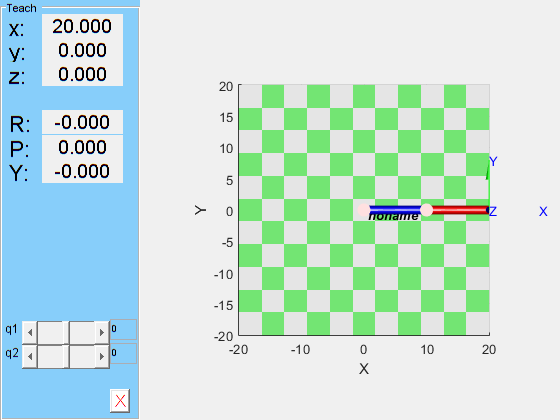

TB0 = getTransformationMatrix(dh, 'alpha')